# FEM_ICA_20250912 Finite Elements Handwork Questions:

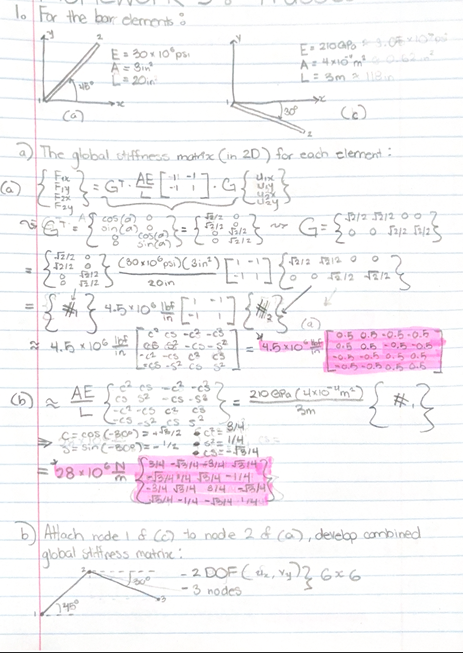

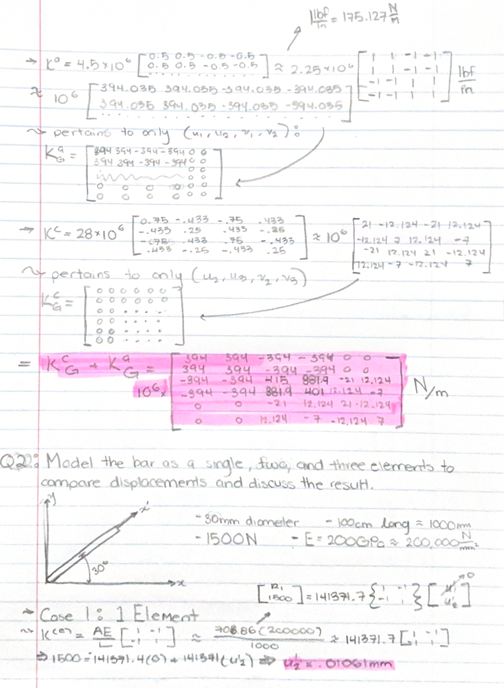

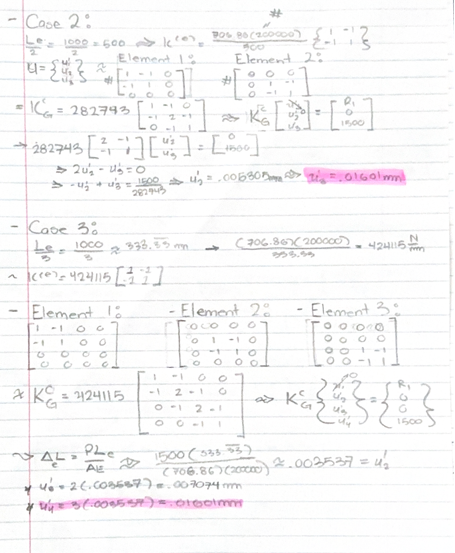

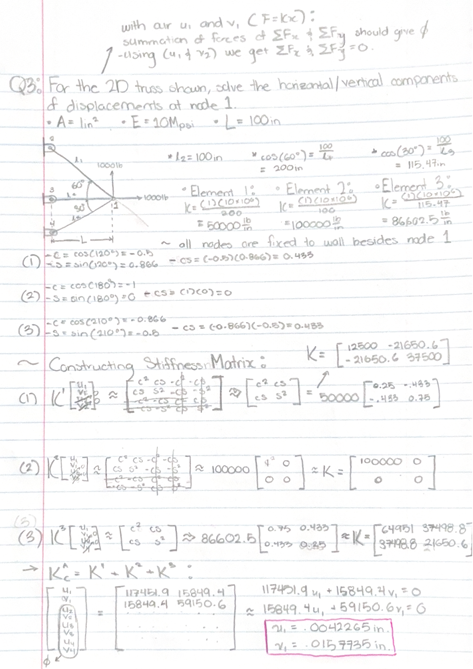

# FEM_ICA_20250912 Finite Elements Question 4 Script

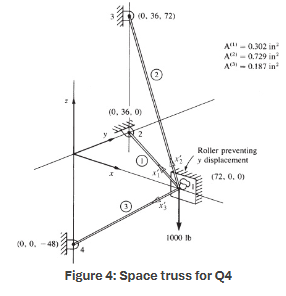

## Knowns

numNodes = 4; %number of nodes
numEle = 3; %number of elements
m = 3; %degrees of freedom

A = [0.302,0.729,0.187]'; %cross-sectional areas for each element
E = 1.2*10^6*[1,1,1]'; %Young's Modulus for each element

% Location in space for each element
xcoords = [72,72,72;0,0,0]';
ycoords = [0,0,0;36,36,0]';
zcoords = [0,0,0;0,72,-48]';

## Calculate element lengths

L = zeros(numEle,1);

for ele = 1:numEle
    L(ele) = sqrt((xcoords(ele,2)-xcoords(ele,1))^2 + ...
                  (ycoords(ele,2)-ycoords(ele,1))^2 + ...
                  (zcoords(ele,2)-zcoords(ele,1))^2);
end

% Calculate stiffness values
k_val = (A.*E)./L;

## Compute element stiffness matrices

% Calculating the rotation coefficients
Cx = zeros(numEle,1);
Cy = zeros(numEle,1);
Cz = zeros(numEle,1);

for ele = 1:numEle
    Cx(ele) = (xcoords(ele,2) - xcoords(ele,1))/L(ele);
    Cy(ele) = (ycoords(ele,2) - ycoords(ele,1))/L(ele);
    Cz(ele) = (zcoords(ele,2) - zcoords(ele,1))/L(ele);
end

## Construct lambda matrices

lambda = zeros(m,m,numEle);

for ele = 1:numEle

    a = Cx(ele);
    b = Cy(ele);
    c = Cz(ele);

    lambda(:,:,ele) = k_val(ele)*[a^2, a*b, a*c; ...
                                  b*a, b^2, b*c; ...
                                  c*a, c*b, c^2];

end

## Construct element stiffness matrices

k = zeros(m*2,m*2,numEle);

for ele = 1:numEle

    eleLambda = lambda(:,:,ele);

    k(:,:,ele) = [ eleLambda, -eleLambda; ...
                  -eleLambda,  eleLambda];

end

## Assemble stiffness matrices into global matrix

K = zeros(numNodes*m,numNodes*m);

% Each row contains the two nodes connected by an element
eleNodes = [1 2;
            1 3;
            1 4];

for ele = 1:numEle

    node1 = eleNodes(ele,1);
    node2 = eleNodes(ele,2);

    % Global degrees of freedom for both nodes
    dofs = [(node1-1)*m + (1:m), ...
            (node2-1)*m + (1:m)];

    % Superposition of element stiffness into global stiffness matrix
    K(dofs,dofs) = K(dofs,dofs) + k(:,:,ele);

end

## Compute force and displacement vectors using the global stiffness matrix

F = zeros(numNodes*m,1);
U = zeros(numNodes*m,1);

% Applied force at node 1
F([1,3]) = [850,-1000];

% v1 is constrained by the roller, so only u1 and w1 are unknown
F_trim = F([1,3],1);
K_trim = K([1,3],[1,3]);

% Solve for displacement at node 1
U_trim = K_trim\F_trim;

% Populate full displacement vector
U(1) = U_trim(1); %u1
U(2) = 0;         %v1
U(3) = U_trim(2); %w1

## Find element displacement vectors

eleU = zeros(m*2,numEle);

for ele = 1:numEle

    node1 = eleNodes(ele,1);
    node2 = eleNodes(ele,2);

    dofs = [(node1-1)*m + (1:m), ...
            (node2-1)*m + (1:m)];

    eleU(:,ele) = U(dofs);

end

## Find axial forces and stresses

axialForce = zeros(numEle,1);
sigma = zeros(numEle,1);

for ele = 1:numEle

    % Displacement at first and second node of element
    u1e = eleU(1:3,ele);
    u2e = eleU(4:6,ele);

    % Direction cosine vector
    direction = [Cx(ele); Cy(ele); Cz(ele)];

    % Axial deformation of the element
    delta = direction'*(u2e-u1e);

    % Axial force
    axialForce(ele) = k_val(ele)*delta;

    % Stress
    sigma(ele) = axialForce(ele)/A(ele);

end

# FEM_ICA_20250912 Finite Elements Question 5 Script

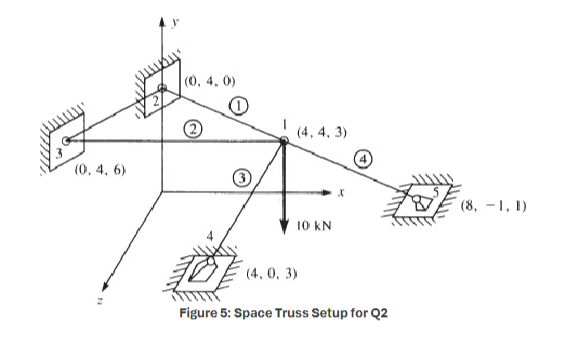

%% Question 5 - Space Truss
clear;

%% Knowns

numNodes = 5; % number of nodes
numEle = 4;   % number of elements
m = 3;        % 3 DOFs per node: x, y, z

% All elements have the same cross-sectional area
A = 10e-4*ones(numEle,1); % m^2

% All elements have the same Young's Modulus
E = 210e9*ones(numEle,1); % Pa


%% Location in space for each element

% Element 1 connects node 2 to node 1
% Node 2 = (0,4,0)
% Node 1 = (4,4,3)

% Element 2 connects node 3 to node 1
% Node 3 = (0,4,6)
% Node 1 = (4,4,3)

% Element 3 connects node 4 to node 1
% Node 4 = (4,0,3)
% Node 1 = (4,4,3)

% Element 4 connects node 1 to node 5
% Node 1 = (4,4,3)
% Node 5 = (8,-1,1)

xcoords = [0,4;
           0,4;
           4,4;
           4,8];

ycoords = [4,4;
           4,4;
           0,4;
           4,-1];

zcoords = [0,3;
           6,3;
           3,3;
           3,1];


%% Calculate element lengths

L = zeros(numEle,1);

for ele = 1:numEle

    L(ele) = sqrt((xcoords(ele,2)-xcoords(ele,1))^2 + ...
                  (ycoords(ele,2)-ycoords(ele,1))^2 + ...
                  (zcoords(ele,2)-zcoords(ele,1))^2);

end


%% Calculate stiffness values

% Basic axial stiffness for each bar:
%
% k = AE/L

k_val = (A.*E)./L;


%% Calculate direction cosines

Cx = zeros(numEle,1);
Cy = zeros(numEle,1);
Cz = zeros(numEle,1);

for ele = 1:numEle

    Cx(ele) = (xcoords(ele,2)-xcoords(ele,1))/L(ele);

    Cy(ele) = (ycoords(ele,2)-ycoords(ele,1))/L(ele);

    Cz(ele) = (zcoords(ele,2)-zcoords(ele,1))/L(ele);

end


%% Construct lambda matrices

lambda = zeros(m,m,numEle);

for ele = 1:numEle

    a = Cx(ele);
    b = Cy(ele);
    c = Cz(ele);

    lambda(:,:,ele) = k_val(ele)* ...
        [a^2, a*b, a*c;
         b*a, b^2, b*c;
         c*a, c*b, c^2];

end


%% Construct full element stiffness matrices

k = zeros(m*2,m*2,numEle);

for ele = 1:numEle

    eleLambda = lambda(:,:,ele);

    k(:,:,ele) = ...
        [ eleLambda, -eleLambda;
         -eleLambda,  eleLambda];

end


%% Assemble global stiffness matrix

% 5 nodes * 3 DOFs = 15 x 15 global stiffness matrix

K = zeros(numNodes*m,numNodes*m);


% Define which nodes are connected by each element

eleNodes = [2 1;
            3 1;
            4 1;
            1 5];


for ele = 1:numEle

    node1 = eleNodes(ele,1);
    node2 = eleNodes(ele,2);

    % Find global DOFs for both nodes
    dofs = [(node1-1)*m + (1:m), ...
            (node2-1)*m + (1:m)];

    % Superimpose element stiffness into global matrix
    K(dofs,dofs) = K(dofs,dofs) + k(:,:,ele);

end


%% Construct force and displacement vectors

F = zeros(numNodes*m,1);
U = zeros(numNodes*m,1);


% Node 1 DOFs:
%
% DOF 1 = x
% DOF 2 = y
% DOF 3 = z
%
% Applied force is 10 kN downward in y direction

F(2) = -10000;


%% Apply boundary conditions

% Nodes 2, 3, 4, and 5 are fixed.
%
% Node 1 is free in x, y, and z.
%
% Therefore the only unknown displacement DOFs are:
%
% u1, v1, w1
%
% Global DOFs [1 2 3]

F_trim = F([1,2,3]);

K_trim = K([1,2,3],[1,2,3]);


%% Solve displacement at node 1

U_trim = K_trim\F_trim;


% Put the calculated displacements into full U vector

U(1) = U_trim(1); % u1
U(2) = U_trim(2); % v1
U(3) = U_trim(3); % w1


%% Construct element displacement vectors

eleU = zeros(m*2,numEle);

for ele = 1:numEle

    node1 = eleNodes(ele,1);
    node2 = eleNodes(ele,2);

    dofs = [(node1-1)*m + (1:m), ...
            (node2-1)*m + (1:m)];

    eleU(:,ele) = U(dofs);

end


%% Calculate element axial forces

axialForce = zeros(numEle,1);

for ele = 1:numEle

    % Displacement of first node
    u1e = eleU(1:3,ele);

    % Displacement of second node
    u2e = eleU(4:6,ele);

    % Direction cosine vector
    direction = [Cx(ele);
                 Cy(ele);
                 Cz(ele)];

    % Axial deformation
    delta = direction'*(u2e-u1e);

    % Axial member force
    axialForce(ele) = k_val(ele)*delta;

end


%% Calculate reaction forces

% KU gives all nodal forces produced by the structure.
%
% Subtract the applied external force to obtain reactions.

R = K*U - F;


%% Formatted displacement output

fprintf('\nNODE 1 DISPLACEMENTS\n');
fprintf('-----------------------------\n');

fprintf('u1 = %12.6e m\n',U(1));
fprintf('v1 = %12.6e m\n',U(2));
fprintf('w1 = %12.6e m\n',U(3));


%% Formatted element force output

fprintf('\nELEMENT FORCES\n');
fprintf('--------------------------------------\n');

for ele = 1:numEle

    if axialForce(ele) > 0
        condition = 'Tension';
    elseif axialForce(ele) < 0
        condition = 'Compression';
    else
        condition = 'Zero Force';
    end

    fprintf('Element %d = %10.3f N   %s\n', ...
        ele,axialForce(ele),condition);

end


%% Formatted reaction force output

fprintf('\nREACTION FORCES\n');
fprintf('--------------------------------------------------\n');

for node = 2:numNodes

    dofs = (node-1)*m + (1:m);

    fprintf('Node %d: Rx = %10.3f N, Ry = %10.3f N, Rz = %10.3f N\n', ...
        node,R(dofs(1)),R(dofs(2)),R(dofs(3)));

end